# Project 1 MA 493 

Authored: Sarah Bird (The Do-er), Nicholas Gawron (Group Parent), Jamie Loring (The Facilitator), Andrea Stancescu (The Caffeinated)

Due Date: 3/9/2022 

## Part I: k++ Initalization 

### Concept

$k$++ initialization can be summarized as follows:  To begin with, the first representative vector $\vec{c_1}$ should be chosen randomly from the data.  The next vector $\vec{c_2}$ should be chosen such that it's the furthest data point value away from $\vec{c_1}$.  This process should be repeated until all vectors $\vec{c_i}$ are assigned, such that the inital value of the next representative vector $\vec{c_l}$ is the data point that is furthest away from the nearest vector among $\vec{c_1}$, ..., $\vec{c_{l-1}}$.

Clear the workspace and close all figure windows

clear;
close all
clc

Load the data for this question

load Q1data.mat

### **Random Initialization **

We will be sampling components using a uniform distribution for each component on the interval [-1.2, 1.2].

Set the number of data vectors (n) and the dimension of the data space (m)

[n,m] = size(XData);

Set the number of clusters $k$

k=5;

Assign each data vector, randomly to one of the $k$ clusters

IndexSeti = randi(k,n,1);

Create data structures to store the weight vectors for cluster $c_i$ and the weight vectors from the previous iteration (cPrev)

ci = zeros(k,m);
cPrev = zeros(k,m);

Randomly initialize the weight vectors so that each component is sampled from the interval [-1.2,1.2]

ci = -1.2 + 2.4*rand(k,m);

### **The Alternating Minimization Scheme**

Calls the function that will perform the Alternating Minimization Scheme

[IndexSetf,cf] = kmeans493(XData,k,IndexSeti,ci);

The first panel below shows the random initialization prior to any k-means clustering. Then, the second panel shows the clustering after performing the k-means alternting minimization scheme.

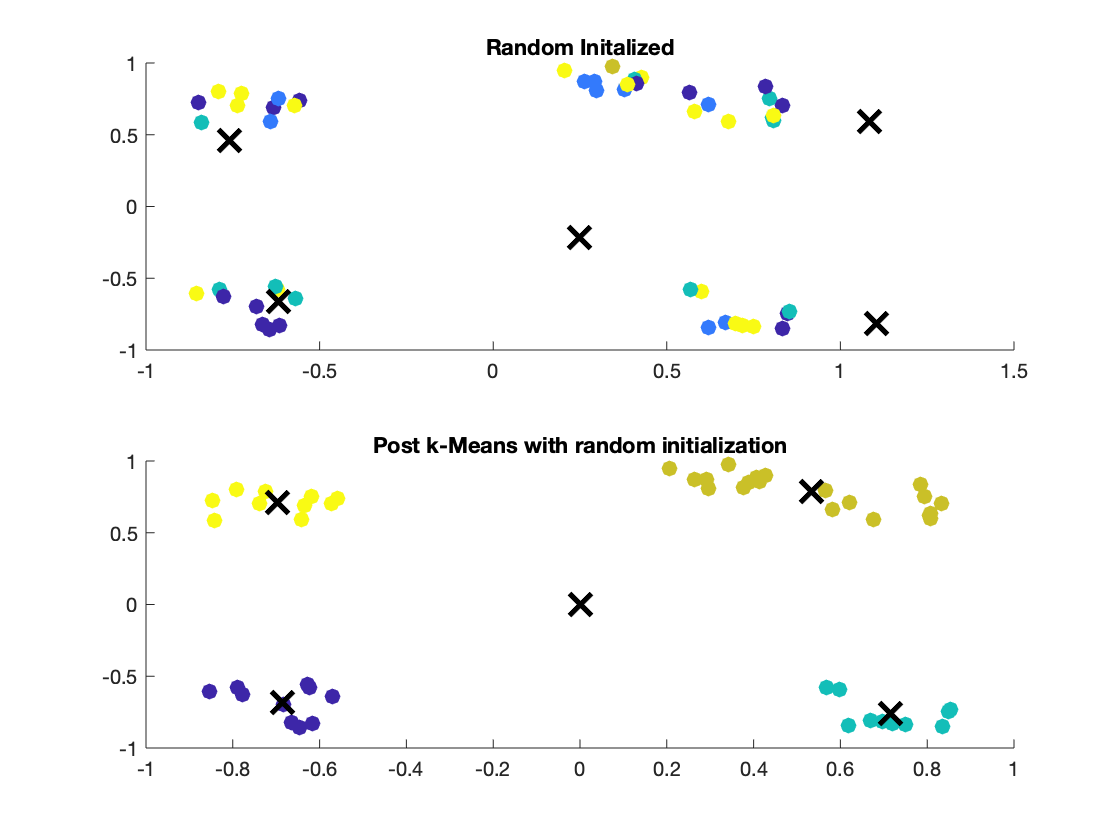

figure;
subplot(2,1,1)
  scatter(XData(:,1),XData(:,2),64,IndexSeti,'filled')
        hold on; 
        plot(ci(:,1),ci(:,2),'kx','MarkerSize',15,'LineWidth',3)
        title('Random Initalized')
        
subplot(2,1,2)

    scatter(XData(:,1),XData(:,2),64,IndexSetf,'filled')
        hold on;
        plot(cf(:,1),cf(:,2),'kx','MarkerSize',15,'LineWidth',3)
        title('Post k-Means with random initialization')

### The k++ Initialization

Calls the function that will perform the $k$++ initialization

[ci,IndexSeti] = KPlusPlusInit(XData,k);
[IndexSetf,cf] = kmeans493(XData,k,IndexSeti,ci);

The first panel below shows the $k$++ initialization prior to any k-means clustering. Then, the second panel shows the clustering after performing the k-means alternating minimization scheme.

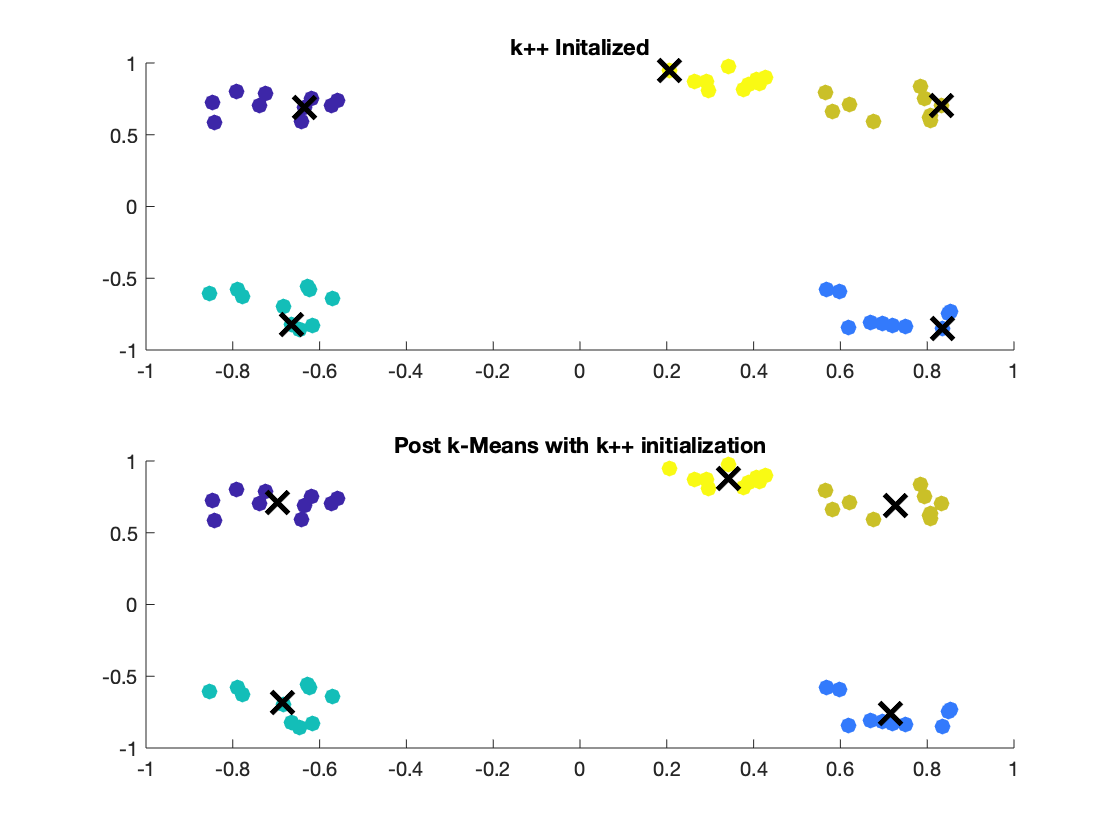

figure;
subplot(2,1,1)
  scatter(XData(:,1),XData(:,2),64,IndexSeti,'filled')
        hold on; 
        plot(ci(:,1),ci(:,2),'kx','MarkerSize',15,'LineWidth',3)
        title('k++ Initalized')
        
subplot(2,1,2)

    scatter(XData(:,1),XData(:,2),64,IndexSetf,'filled')
        hold on;
        plot(cf(:,1),cf(:,2),'kx','MarkerSize',15,'LineWidth',3)
        title('Post k-Means with k++ initialization')

### 10 Realizations of K-Means

This first section runs 10 realizations of the clustering for the random initialization

% intializes the vectors to store overall coherence
OvCO_forkPP = zeros(1,10);
OvCO_forRand = zeros(1,10); 

% sets k clusters to be 5
k=5; 

% runs 10 realizations
for realz = 1:10
    
    [n,m]= size(XData);
    IndexSeti = randi(k,n,1);
    ci = -1.2 + 2.4*rand(k,m);   
    
    [IndexSetf,cf]= kmeans493(XData,k,IndexSeti,ci);
    OvCo=oaco(XData,IndexSetf,cf);
    OvCO_forRand(:,realz) = OvCo ;
    
end

This next section runs 10 realizations of the clustering for the $k$++ initialization

for realz = 1:10     
    [ci,IndexSeti]=KPlusPlusInit(XData,k);


    [IndexSetf,cf]= kmeans493(XData,k,IndexSeti,ci);

    OvCo=oaco(XData,IndexSetf,cf);
    
    OvCO_forkPP(:,realz) = OvCo ; 

end

To make a conclusion about which initialization yields better performance, we decided to look at the means of the overall coherences for each one.

% prints out the mean overall coherence for each method!
% first for k++ followed by random initalization
mean(OvCO_forkPP)

ans = 0.7737

mean(OvCO_forRand)

ans = 7.1063

### Conclusions

After running through the 20 different realizations of the k-means algorithm, we computed means for the overall coherence of each initialization structure. The mean for the random initialization was found to be 6.4022 while the mean for the $k$++ initialization is 0.7737. The data from these 10 observations points to $k$++ leading to a better performance as it minimizes the overall coherence value more effectively. A potential explanation for this is that $k$++ uses the data vectors themselves, not just a random number generated.

## Part II: Elbow Method

### Concept

The Elbow Method can be summarized as follows:  To begin with, a set of successive values should be picked to represent the possible number of clusters.  For each value of $k$, the k-means clustering algorithm should be run and then the overall coherence should be calculated.  These overall coherence values, for each value of $k$, should be graphed (on the same plot), and the "elbow" in this graph is the point where there is a sharp change in slope.  This "elbow" corresponds to the best value of $k$.

### Generalized Code

Setting intialization values and vectors, where rows represents the number of initializations used, and columns are the values of $k$ for each initialization scheme

suck = 8;
initalz = 5; 

mat2PlotKPP = zeros(initalz,suck); 
mat2PlotRand = zeros(initalz,suck);

Getting the data values needed for graphing the Elbow Method -- $k$++ initialization first, then random initialization

for k=1:suck
   
    for realz = 1:initalz
        
        [ci,IndexSeti]=KPlusPlusInit(XData,k);
        [IndexSetf,cf]= kmeans493(XData,k,IndexSeti,ci);
    
        OvCo = oaco(XData,IndexSetf,cf);
        mat2PlotKPP(realz,k) = OvCo; 
    end 
    
    for realz = 1:initalz
        
        [n,m]= size(XData);
        IndexSeti = randi(k,n,1);
        ci = -1.2 + 2.4*rand(k,m);
        [IndexSetf,cf]= kmeans493(XData,k,IndexSeti,ci);
    
        OvCo=oaco(XData,IndexSetf,cf);
        mat2PlotRand(realz,k) = OvCo; 
    end 
      
end

Creates the Elbow Method plots for $k$++ initialization and random initialization, respectively

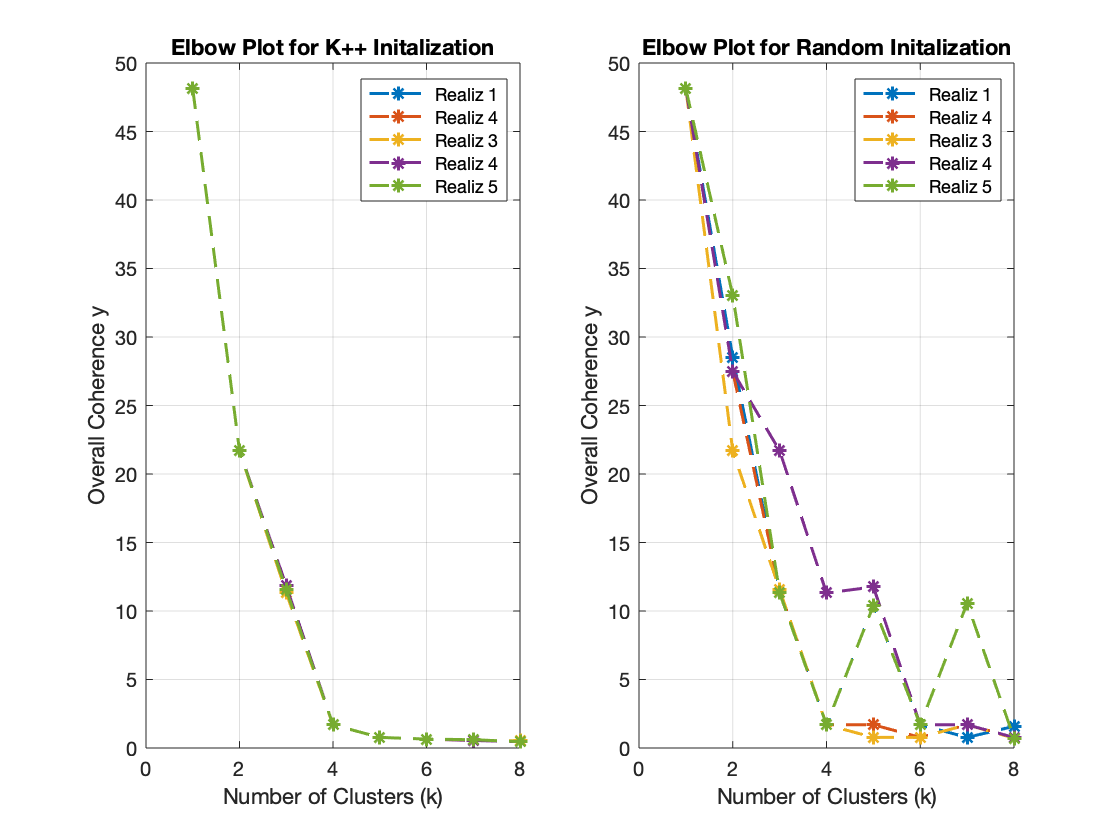

subplot(1,2,1)
for iter = 1:5
    plot(1:suck, mat2PlotKPP(iter,:),'LineWidth',1.5,'Marker',"*",'LineStyle','--')
    hold on
    title('Elbow Plot for K++ Initalization')
    xlabel('Number of Clusters (k)')
    ylabel('Overall Coherence y')
    grid on
end 
legend('Realiz 1','Realiz 4','Realiz 3','Realiz 4','Realiz 5')


hold on 

subplot(1,2,2)
for iter = 1:5
    plot(1:suck, mat2PlotRand(iter,:),'LineWidth',1.5,'Marker',"*",'LineStyle','--')
    hold on
    title('Elbow Plot for Random Initalization')
    xlabel('Number of Clusters (k)')
    ylabel('Overall Coherence y')
    grid on
end
legend('Realiz 1','Realiz 4','Realiz 3','Realiz 4','Realiz 5')
hold off

### Discussion on Optimal k per Initialization

Looking at the two plots that are created from the Elbow Method code, we can see that the results definitely vary between the two different types of initalizations. It appears that $k$++ initialization has less variability between the different realizations of the data. Utilizing the Elbow Method, our group determined that $k$++ initalization minimized the overall coherency most accurately around $k=4$ clusters. Random initalization had more variablility between the realizations of the data. From the plot we obtained, our group determined that either 3 or 4 clusters minimized overall coherency. However, the overall coherency was much higher on average than the $k$++ initalization scheme.

Keeping in mind the discussion of variability in the previous paragraph, we can see that when using the $k$++ initalization scheme, we can be more certain about the number of clusters needed to minimize the coherence, which leads to a better clustering process.

## Part III: MNIST Application

Primer code needed for this application

NImages = 100;

[imgs, labels] = readMNIST('testImages','testLabels', NImages, 0);

% Example of how to convert the first 10 images into vectors for input into
% the clustering algorithm

m = 20*20;
v = zeros(1,m);
XData3 = zeros(NImages,m);

for i=1:NImages
    XData3(i,:) = reshape(imgs(:,:,i),[1,m]);
end

Performs k-means clustering with $k$++ initialization on the first 100 images from the MNIST data set with $k=3$ through $k=10$

k_vec = 3:10;
initial_z = 5;
plot3_kpp = zeros(initial_z,length(k_vec));

figure;

for j=1:length(k_vec)
    for realz = 1:initial_z    
        [ci,IndexSeti]=KPlusPlusInit(XData3,k_vec(j),42);
        [IndexSetf,cf]= kmeans493(XData3,k_vec(j),IndexSeti,ci);
    
        OvCo = oaco(XData3,IndexSetf,cf);
        plot3_kpp(realz,j) = OvCo; 
    end
end

Creating the plot using the Elbow Method for $k=3$ through $k=10$

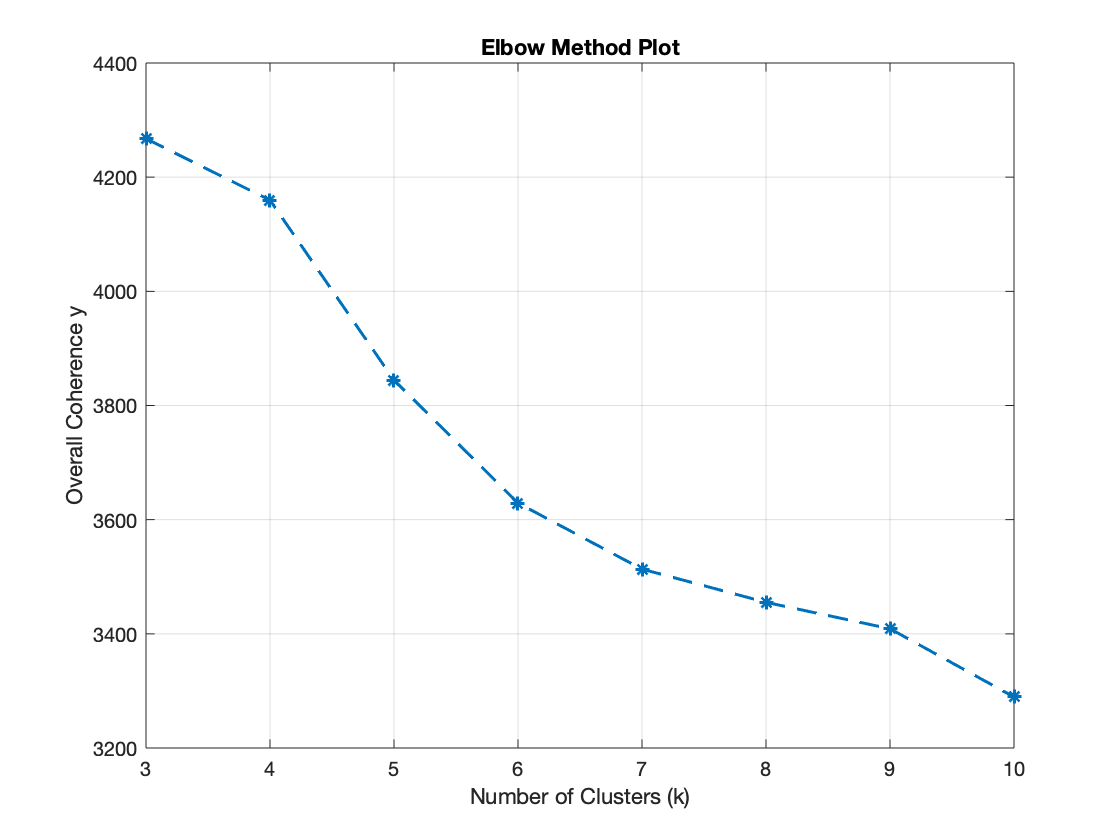

for i = 1:5
    plot(k_vec, plot3_kpp(i,:),'LineWidth',1.5,'Marker',"*",'LineStyle','--')
    hold on
    title('Elbow Method Plot')
    xlabel('Number of Clusters (k)')
    ylabel('Overall Coherence y')
    grid on
    hold off
end 

Based on the Elbow Method graph produced, the "best" value for the number of clusters $k$ is $k=6$

### All Images from Each Cluster

"Primer code" for determining a success score using $k=6$

The images below are associated with cluster 1.
 We note that the most common number that has appeared in this cluster is 1.

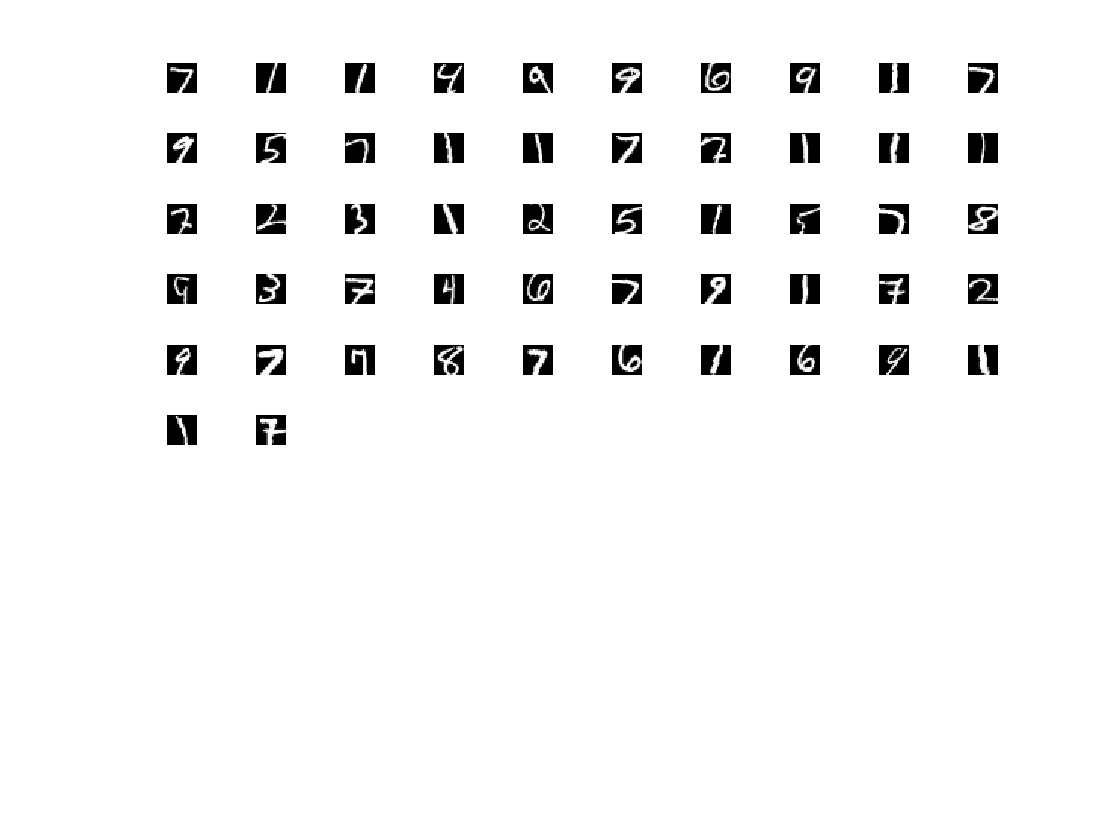

The images below are associated with cluster 2.
 We note that the most common number that has appeared in this cluster is 0.

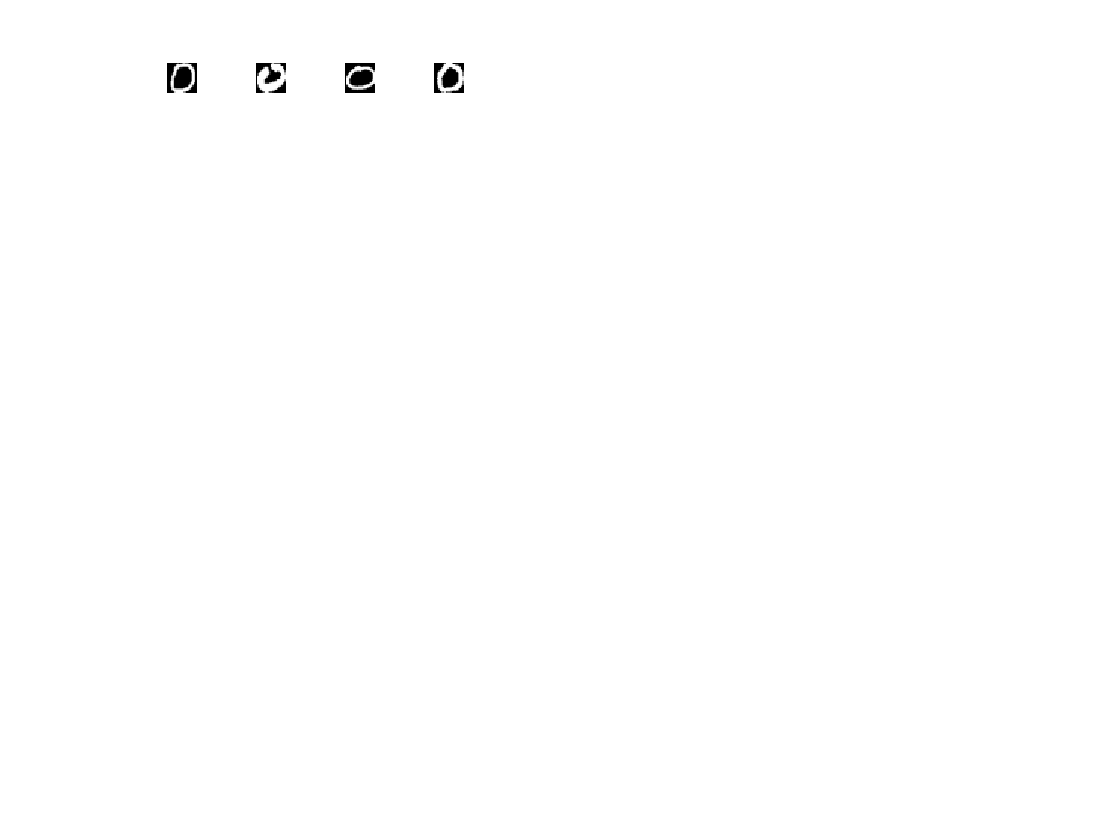

The images below are associated with cluster 3.
 We note that the most common number that has appeared in this cluster is 3.

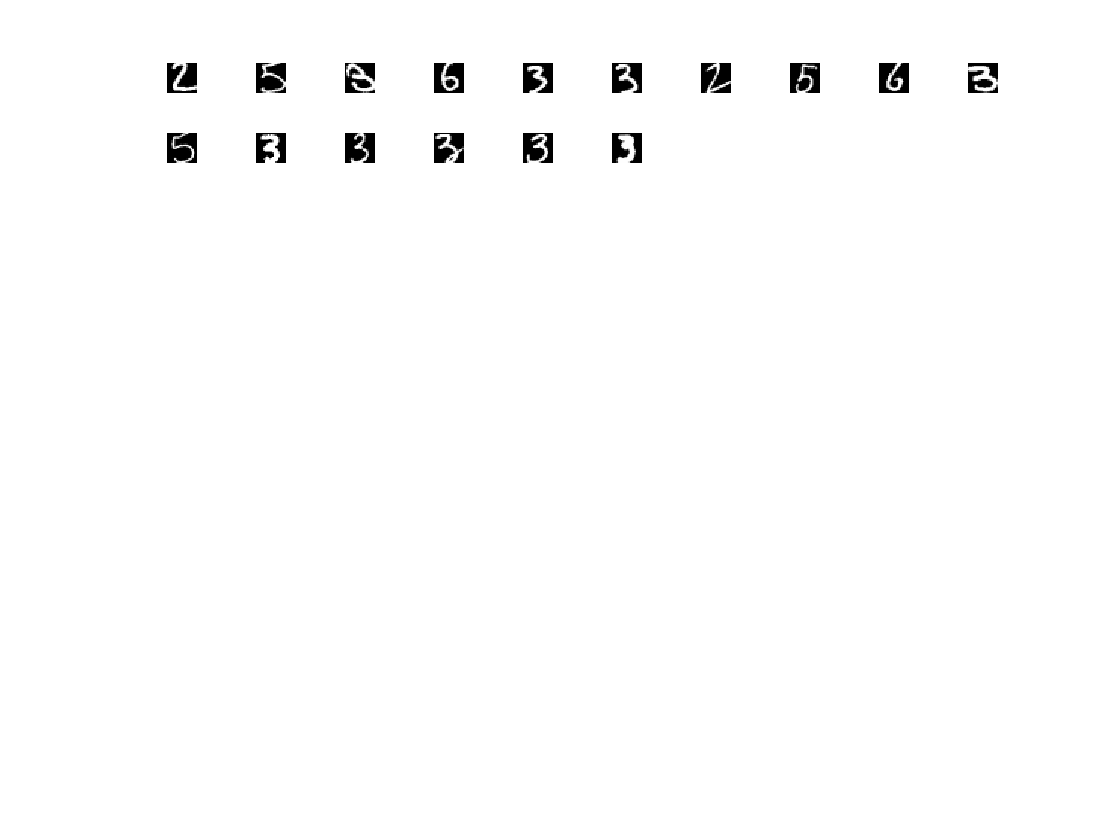

The images below are associated with cluster 4.
 We note that the most common number that has appeared in this cluster is 2.

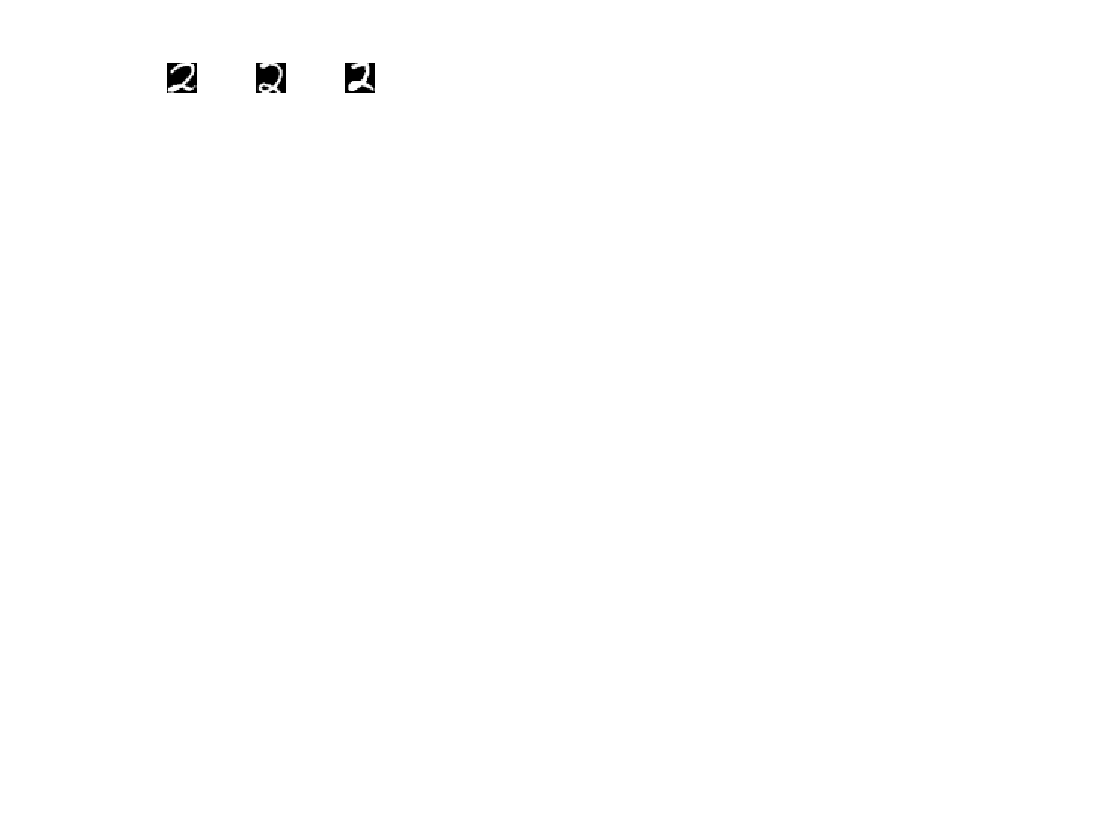

The images below are associated with cluster 5.
 We note that the most common number that has appeared in this cluster is 4.

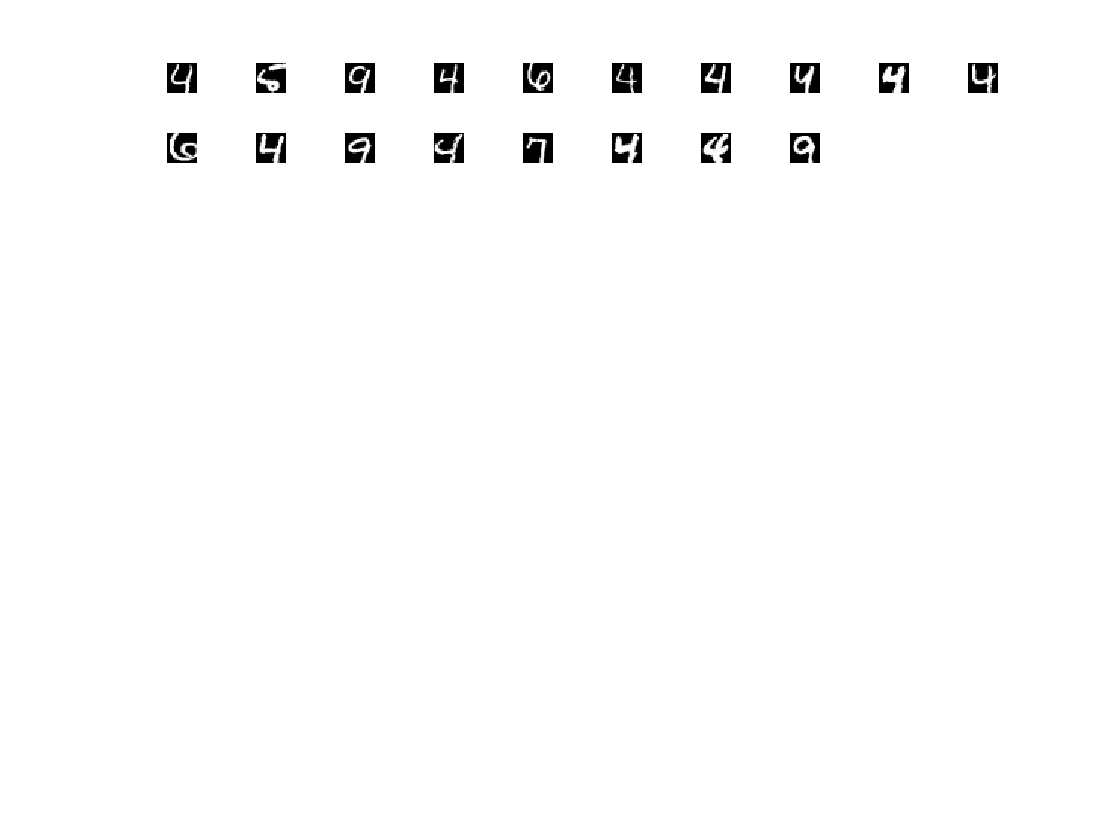

The images below are associated with cluster 6.
 We note that the most common number that has appeared in this cluster is 0.

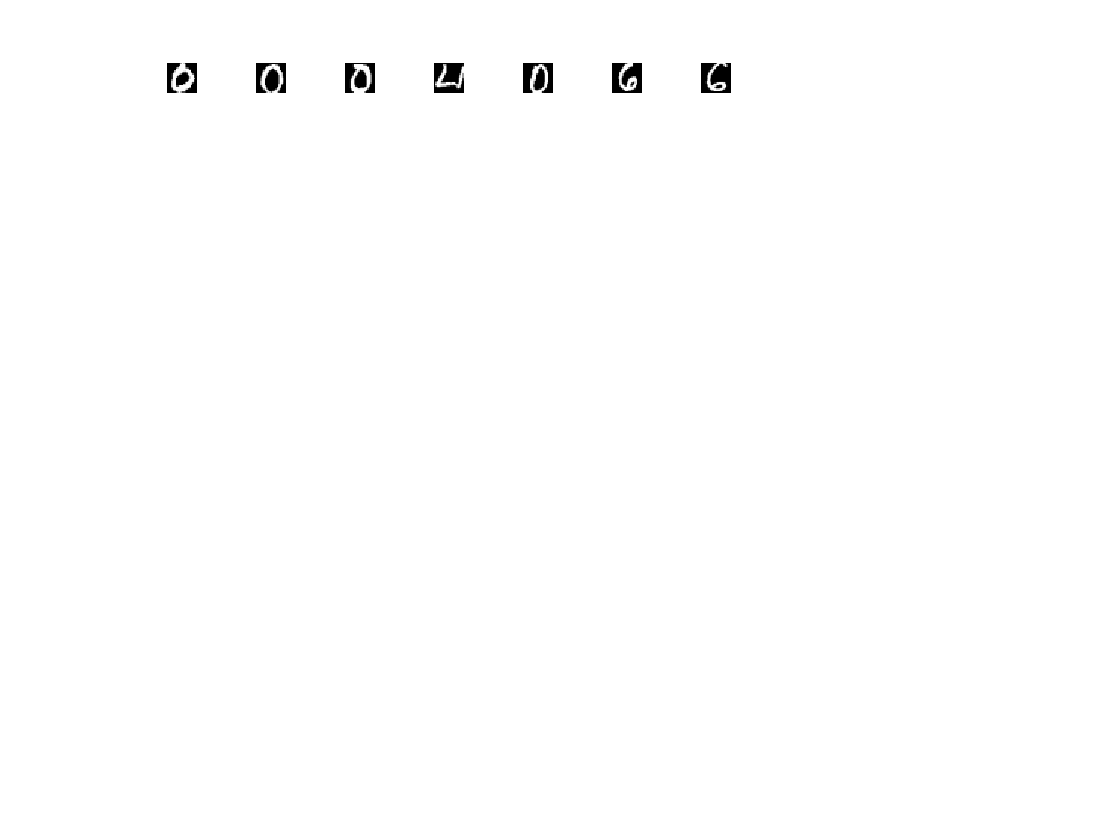

numim = 100; % number of images
% use parts of Haider Code to extract data frame from 100 images 
% 400 cols for 20 x 20 pixels 

[XDataM ,labels2test]= DatHaider(numim);

% use k = 6 from previous elbow graph! 
k_fromelbow=6;
    

% initalizes and does kmeans 
[c,IndexSeti]=KPlusPlusInit(XDataM,k_fromelbow,42);
[IndexSetf, cf] = kmeans493(XDataM,k_fromelbow,IndexSeti,c);

% for the  cluster we...
for val_k= 1:k_fromelbow 

    figure;    
    modeNum=mode(labels2test(IndexSetf==val_k));
    fprintf(['The images below are associated with cluster %d.\n ' ...
        'We note that the most common number that has appeared in this cluster' ...
        ' is %d.'], val_k,modeNum);



% look at all the points in this cluster from k means 
    for i=1:sum(IndexSetf==val_k)
       % creates the rows and coloumns for images in a cluster
        rows_img = round(numim/10);
        cols_img = round(numim/10);
       %creates a subplot for a certain cluster k
       subplot(rows_img,cols_img,i)
       %and shows all the images associated with that cluster
       Cluster_image = XDataM(IndexSetf==val_k,:);
       currImg = reshape(Cluster_image(i,:),[20,20]);
       imshow(currImg,'InitialMagnification',1000) 
    end
    
end 

#### Success Score

Calculating the actual success score (using $k=6$)

ClusterMostOccurNum = [1 0 3 2 4 0];

expLabs = zeros(100,1); 

for val_k = 1:k_fromelbow
    WhereImagesR=IndexSetf==val_k;
    expLabs = ClusterMostOccurNum(val_k).*(WhereImagesR)+expLabs ;
end 

SucScore = sum(expLabs == labels2test)/100;

pct = SucScore*100

pct = 45

From the code above, we see that clustering of the digits in the MNIST data set with $k=6$ clusters gives us a 45% accuracy.

#### Discussion of Clusters

Provide examples of two clusters, including images, that performed well in detecting similar patterns and an example of one cluster that performed less well. Use these examples to discuss the strengths and limitations of this overall approach in the context of this application.

## Part IV: Bonus

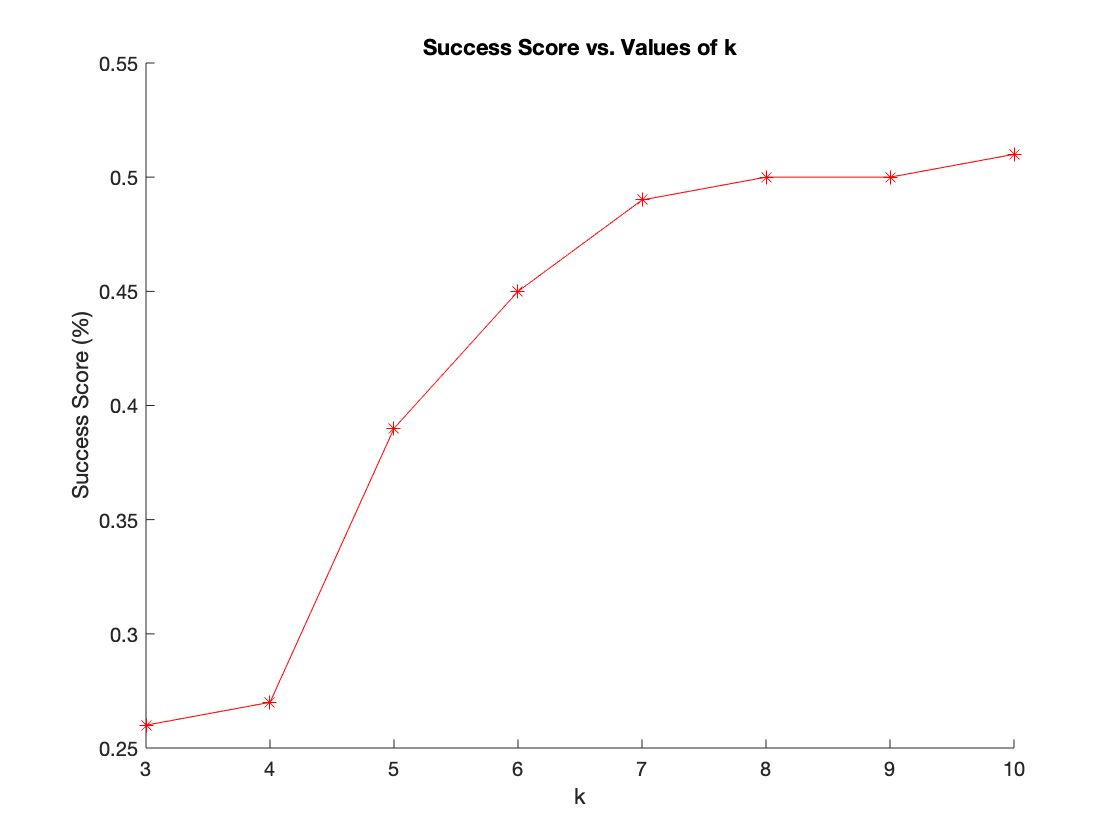

BonusSuck = 10; 

numim = 100; % number of images
% use parts of Haider Code to extract data frame from 100 images 
% 400 cols for 20 x 20 pixels 

[XDataM ,labels2test]= DatHaider(numim);

SucScoresforAll = zeros(1,8);

% calc success score for each k
for k_to_test =3:BonusSuck
    
    %initalizes and does kmeans 
    [c,IndexSeti]=KPlusPlusInit(XDataM,k_to_test,42);
    [IndexSetf, cf] = kmeans493(XDataM,k_to_test,IndexSeti,c);
        
    MostOccurNum = zeros(1,k_to_test);
    expLabs = zeros(100,1);
    
    % for the  cluster we...
    for val_k= 1:k_to_test
        % computes the number that occurs most in the label 
        MostOccurNum(val_k)  =  mode(labels2test(IndexSetf==val_k));
        %find location of image
        WhereImagesR=IndexSetf==val_k;
        %update expiermental labels with mode of image number
        expLabs = MostOccurNum(val_k).*(WhereImagesR)+expLabs ;
    end 

        % computes the success score!
        SucScore = sum(expLabs == labels2test)/100;
        % success score stored as a matrix 
        SucScoresforAll(val_k-2)= SucScore; 
        
end 


%plots the images
figure;

hold on
plot(3:BonusSuck,SucScoresforAll,'r*-')
title('Success Score vs. Values of k')
xlabel('k')
ylabel('Success Score (%)')
hold off

Looking at the graph output here, we see that the highest success score occurs at $k=10$ (51%), while the elbow method yields a success score of 45% (at $k=6$).  It makes sense that the highest success score occurs at a larger value of $k$ than the elbow method shows because having more clusters allows for more differences in images to be separated, therefore resulting in higher accuracy.  We found it interesting that the success score seemed to start leveling off after reaching $k=7$.

## Functions

KPlusPlusInIt: This function establishes the $k$++ initalization for k-means clustering algorithm. It takes in a parameter of x and y values called XData. It also takes in a parameter, $k$, which is the number of clusters.

function [c,IndexSeti]= KPlusPlusInit(XData,k,varargin)


% returns the k num of clusters in the matrix c 
% IndexSeti  is the inital clustering for k means 

% XData  is input data n by m for m dimensional 
% k - num of clusters 
 %varargin{1} - set the inital centriod value!

[n,m]=size(XData);

% Establishes Index Set
% first is theinital index set
IndexSeti = randi(k,n,1);
IndexSet = IndexSeti; 
%haider likes zero initalization! 
c = zeros(k,m);

%%%%%%% Gets C_1

if nargin == 2
    % first step of k++
    randIndex = randi(n);

    % first cluster rep vector!
    c(1,:)= XData(randIndex,:);
else 
     SetInit42 = varargin{1}; 
     c(1,:) = XData(SetInit42,:);
end 


%%
% Create a data structure to store closest weight vector for each data
% point
closestCluster=zeros(n,1);


for l = 2:k
    
    % Reassign each data vector to the new, closest cluster
    for d=1:n

        % Store the coordinates of the current data vector
        xD = XData(d,:);

        % Set the minimum distance tracker to be a very large number
        sqDistMin=1e16;

        % Find the closest weight vector (cluster) to the current data
        % vector
        for i=1:l-1
            sqDist = norm(c(i,:)-xD,2);

            % If the distance is less than the current min, assign the
            % current data vector to this cluster
            if sqDist<sqDistMin
                closestCluster(d)=i;
                sqDistMin=sqDist;
            end

        end
    end
    
 
    
    % Update the assignments of the data vectors to their new clusters
    IndexSet = closestCluster;
    
    % sets up a matrix [distance , data point] for each max dist point per
    % cluster initalizes values to zero!
    % note we use 1+m dimensions since we need m dimensions to store the
    % cluster value 
    % AND the additional one is used to store the distnace
    DistanceANDClusterCani = zeros(l-1,1+m);
    
    
    % we have l-1 clusters looking for the l th cluster
    for y = 1:l-1
        % fetches points closest to y-th cluster
        PointsClosest2y = XData(IndexSet ==y,:);
        % computes the distance from closest points to the y-th cluster
        % gets the max!
        % 2 in the sum lets us sum by row!
        [Max_dist_forClosestClus,IndexInClosest] = max (sum( (PointsClosest2y -c(y,:)).^2,2));
        DistanceANDClusterCani(y,:)= [Max_dist_forClosestClus,PointsClosest2y(IndexInClosest,:)];
    end 
    [~, NextCentriodLoc]= max(DistanceANDClusterCani(:,1));
    c(l,:) = DistanceANDClusterCani(NextCentriodLoc,2:end);
end 

   for d=1:n

        % Store the coordinates of the current data vector
        xD = XData(d,:);

        % Set the minimum distance tracker to be a very large number
        sqDistMin=1e16;

        % Find the closest weight vector (cluster) to the current data
        % vector
        for i=1:k
            sqDist = norm(c(i,:)-xD,2);

            % If the distance is less than the current min, assign the
            % current data vector to this cluster
            if sqDist<sqDistMin
                closestCluster(d)=i;
                sqDistMin=sqDist;
            end

        end
   end
    
   IndexSeti = closestCluster;
   
end

kmeans493: This function carries out the alternating minimization scheme. This function takes in 4 parameters. XData is a matrix of x and y values. $k$ is the number of clusters, IndexSet is the index set for initalization. C is the vector of cluster points. 

function [IndexSetf,cf]=kmeans493(XData,k,IndexSet,c)

[n,m]=size(XData); 

% intialized C_prev 
cPrev = zeros(k,m);

doneFlag=0;

% Keep alternating updates to weight vectors and cluster assignments until weight 
% vectors no longer change their locations

while (~doneFlag)

    % Update the weight vectors in each cluster via the centroid formula
    for i=1:k 

        % Find the indices for all data vectors currently in cluster i
        ClusterIndices = find(IndexSet==i);

        % Find the number of data vectors currently in cluster i
        NumVecsInCluster = size(ClusterIndices,1);

        % Create a data structure to store weight vector for the current
        % cluster
        c(i,:)=0; 

        % Update cluster vector using the centroid formula
        for j=1:NumVecsInCluster
            for l=1:m
                c(i,l) = c(i,l) + XData(ClusterIndices(j,1),l)/NumVecsInCluster;
            end
        end

    end

    
    % Now reassign all data vectors to the closest weight vector (cluster)

    % Create a data structure to store closest weight vector for each data
    % point
    closestCluster=zeros(n,1);

    % Reassign each data vector to the new, closest cluster
    for d=1:n

        % Store the coordinates of the current data vector
        xD = XData(d,:);

        % Set the minimum distance tracker to be a very large number
        sqDistMin=1e16;

        % Find the closest weight vector (cluster) to the current data
        % vector
        for i=1:k
            sqDist = norm(c(i,:)-xD,2);

            % If the distance is less than the current min, assign the
            % current data vector to this cluster
            if sqDist<sqDistMin
                closestCluster(d)=i;
                sqDistMin=sqDist;
            end

        end
    end

    % Update the assignments of the data vectors to their new clusters
    IndexSet = closestCluster;
    
    
    % Terminate the alternating scheme if the weight vectors are unaltered
    % relative to the previous iteration
    if c==cPrev
        doneFlag=1;
    else
        cPrev=c;
    end
end


cf = c ;
IndexSetf = IndexSet; 
end

oaco: This function computes the overall coherence value. It takes in a matrix called XDataf, which is a matrix of x and y values of the data. It also takes in a column vector called IndexSetf which is the final index set. It also takes in a matrix named c which are the final centroid points.

function OvCo=oaco(XDataf,IndexSetf,c)
    % output overall coherence 
        % calculated by summing the coherence from each 
        %cluster sum_{1 to k } ||x_i-c_i||
    % input final indexSet after K-Means is run!
    % input final set of clusters
    % input orginal data of form nxm for n rows of m dimensional data
    OvCo = 0; 
    for i=1:size(c,1) % number of k clusters
        % gets the i-th final cluster points  
        Dist_i =sum(sum((XDataf(IndexSetf==i,:)-c(i,:)).^2,2));
        OvCo = Dist_i + OvCo;
    end 
    
end

readMNIST: Reads digits and labels from raw MNIST data files

function [imgs, labels] = readMNIST(imgFile, labelFile, readDigits, offset)
    
    % Read digits
    fid = fopen(imgFile, 'r', 'b');
    header = fread(fid, 1, 'int32');
    if header ~= 2051
        error('Invalid image file header');
    end
    count = fread(fid, 1, 'int32');
    if count < readDigits+offset
        error('Trying to read too many digits');
    end
    
    h = fread(fid, 1, 'int32');
    w = fread(fid, 1, 'int32');
    
    if offset > 0
        fseek(fid, w*h*offset, 'cof');
    end
    
    imgs = zeros([h w readDigits]);
    
    for i=1:readDigits
        for y=1:h
            imgs(y,:,i) = fread(fid, w, 'uint8');
        end
    end
    
    fclose(fid);
    % Read digit labels
    fid = fopen(labelFile, 'r', 'b');
    header = fread(fid, 1, 'int32');
    if header ~= 2049
        error('Invalid label file header');
    end
    count = fread(fid, 1, 'int32');
    if count < readDigits+offset
        error('Trying to read too many digits');
    end
    
    if offset > 0
        fseek(fid, offset, 'cof');
    end
    
    labels = fread(fid, readDigits, 'uint8');
    fclose(fid);
    
    % Calc avg digit and count
    imgs = trimDigits(imgs, 4);
    imgs = normalizePixValue(imgs);
    %[avg num stddev] = getDigitStats(imgs, labels);
    
end

trimDigits: This function will trim the 4 pixel padding around the digits 

function digits = trimDigits(digitsIn, border)
    dSize = size(digitsIn);
    digits = zeros([dSize(1)-(border*2) dSize(2)-(border*2) dSize(3)]);
    for i=1:dSize(3)
        digits(:,:,i) = digitsIn(border+1:dSize(1)-border, border+1:dSize(2)-border, i);
    end
end

normalizePixValue: This function will normalize pixel values to the [0...1] range

function digits = normalizePixValue(digits)
    digits = double(digits);
    for i=1:size(digits, 3)
        digits(:,:,i) = digits(:,:,i)./255.0;
    end
end